clear; clc; close all;

%%  LOAD & CLEAN DATASET
filePath = "C:\Users\Nishanth\OneDrive\Desktop\city_day.csv";
T = readtable(filePath);

T.Properties.VariableNames = matlab.lang.makeValidName(T.Properties.VariableNames);

fprintf('\nDataset loaded: %d rows, %d columns\n', height(T), width(T));


Dataset loaded: 29531 rows, 16 columns


fprintf('Cities found : %d\n\n', numel(unique(T.City)));

Cities found : 26



%% USER SELECTS PRIMARY POLLUTANT
fprintf('Available pollutants: PM2_5, PM10, NO, NO2, NOx, NH3, CO, SO2, O3, Benzene, Toluene, Xylene\n');

Available pollutants: PM2_5, PM10, NO, NO2, NOx, NH3, CO, SO2, O3, Benzene, Toluene, Xylene


mainPollutant = input('Enter pollutant name for clustering (e.g. PM2_5): ', 's');

if ~ismember(mainPollutant, T.Properties.VariableNames)
    error("Pollutant '%s' not found in dataset!", mainPollutant);
end


%%   COMPUTE CITY-LEVEL FEATURES
% Features per city: Mean, Std, Median, 90th Percentile, Mean AQI

cities    = unique(T.City);
numCities = numel(cities);

featMean   = zeros(numCities, 1);
featStd    = zeros(numCities, 1);
featMedian = zeros(numCities, 1);
featP90    = zeros(numCities, 1);
featAQI    = zeros(numCities, 1);


for i = 1:numCities
    mask = strcmp(T.City, cities{i});
    vals = T.(mainPollutant)(mask);
    aqi  = T.AQI(mask);

    % Clean pollutant values
    vals = vals(~isnan(vals));
    vals = rmoutliers(vals, 'mean', 'ThresholdFactor', 3);

    % Clean AQI values
    aqi = aqi(~isnan(aqi));
    aqi = rmoutliers(aqi, 'mean', 'ThresholdFactor', 3);

    if numel(vals) < 10
        featMean(i) = NaN; featStd(i) = NaN;
        featMedian(i) = NaN; featP90(i) = NaN;
    else
        featMean(i)   = mean(vals);
        featStd(i)    = std(vals);
        featMedian(i) = median(vals);
        featP90(i)    = prctile(vals, 90);
    end

    if numel(aqi) < 5
        featAQI(i) = NaN;
    else
        featAQI(i) = mean(aqi);
    end
end


% Remove cities with insufficient data
valid      = ~any([isnan(featMean) isnan(featStd) isnan(featMedian) ...
                   isnan(featP90)  isnan(featAQI)], 2);
featMean   = featMean(valid);
featStd    = featStd(valid);
featMedian = featMedian(valid);
featP90    = featP90(valid);
featAQI    = featAQI(valid);
cities     = cities(valid);

fprintf('Valid cities for clustering: %d\n\n', numel(cities));

Valid cities for clustering: 26



%% STEP 4 — NORMALISE FEATURE MATRIX
X      = [featMean, featStd, featMedian, featP90, featAQI];
X_norm = zscore(X);


%% STEP 5 — FIND OPTIMAL K via SILHOUETTE SCORE
fprintf('Computing silhouette scores for k = 2 to 6 ...\n');

Computing silhouette scores for k = 2 to 6 ...


maxK      = min(6, numel(cities) - 1);
silScores = zeros(maxK - 1, 1);

for k = 2:maxK
    [idxTmp, ~]    = kmeans(X_norm, k, 'Replicates', 50, 'MaxIter', 500);
    silScores(k-1) = mean(silhouette(X_norm, idxTmp));
    fprintf('  k = %d  |  Silhouette = %.4f\n', k, silScores(k-1));
end

  k = 2  |  Silhouette = 0.5894
  k = 3  |  Silhouette = 0.6583
  k = 4  |  Silhouette = 0.6318
  k = 5  |  Silhouette = 0.5664
  k = 6  |  Silhouette = 0.5966



[~, bestIdx] = max(silScores);
kOpt = bestIdx + 1;
fprintf('\n>> Optimal k = %d\n\n', kOpt);


>> Optimal k = 3



%% STEP 6 — FINAL K-MEANS CLUSTERING
rng(12);
[idx, ~] = kmeans(X_norm, kOpt, 'Replicates', 100, 'MaxIter', 1000, ...
                  'Distance', 'sqeuclidean');


%% STEP 7 — LABEL CLUSTERS BY POLLUTION LEVEL
clusterMeanVal = zeros(kOpt, 1);
for c = 1:kOpt
    clusterMeanVal(c) = mean(featMean(idx == c));
end
[~, order] = sort(clusterMeanVal);
levelNames    = ["Low Pollution", "Moderate Pollution", "High Pollution", ...
                 "Very High Pollution", "Extreme Pollution", "Hazardous Pollution"];
clusterLabels = strings(kOpt, 1);
for c = 1:kOpt
    clusterLabels(order(c)) = levelNames(c);
end


%%  COLOUR SCHEME

colors = [0.18 0.55 0.34;   % green  — Low
          0.95 0.77 0.06;   % yellow — Moderate
          0.85 0.33 0.10;   % orange — High
          0.64 0.08 0.18;   % red    — Very High
          0.30 0.00 0.36;   % purple — Extreme
          0.05 0.05 0.05];  % black  — Hazardous
colors = colors(1:kOpt, :);


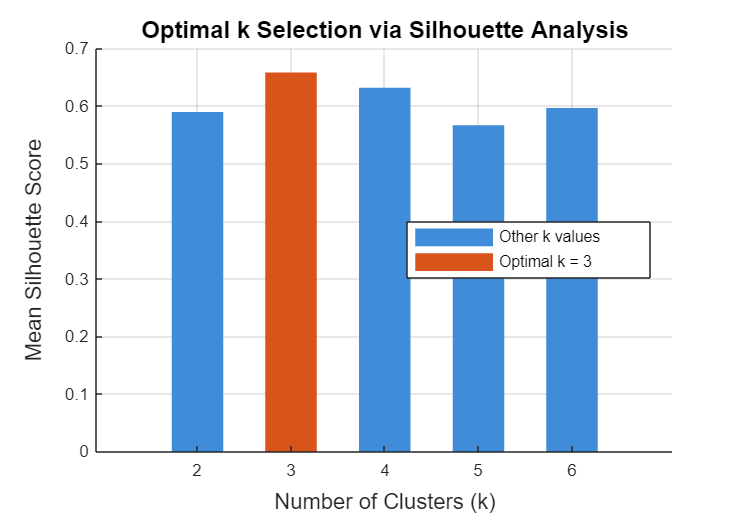

%%  FIGURE 1 — Silhouette Bar Chart (Optimal k)

figure('Name', 'Silhouette Analysis', 'Color', 'w', 'Position', [100 100 540 380]);
bar(2:maxK, silScores, 0.55, 'FaceColor', [0.25 0.55 0.85], 'EdgeColor', 'none');
hold on;
bar(kOpt, silScores(kOpt-1), 0.55, 'FaceColor', [0.85 0.33 0.10], 'EdgeColor', 'none');
xlabel('Number of Clusters (k)', 'FontSize', 12);
ylabel('Mean Silhouette Score',  'FontSize', 12);
title('Optimal k Selection via Silhouette Analysis', 'FontSize', 13, 'FontWeight', 'bold');
xticks(2:maxK);
legend({'Other k values', sprintf('Optimal k = %d', kOpt)}, 'Location', 'best');
grid on; box off;

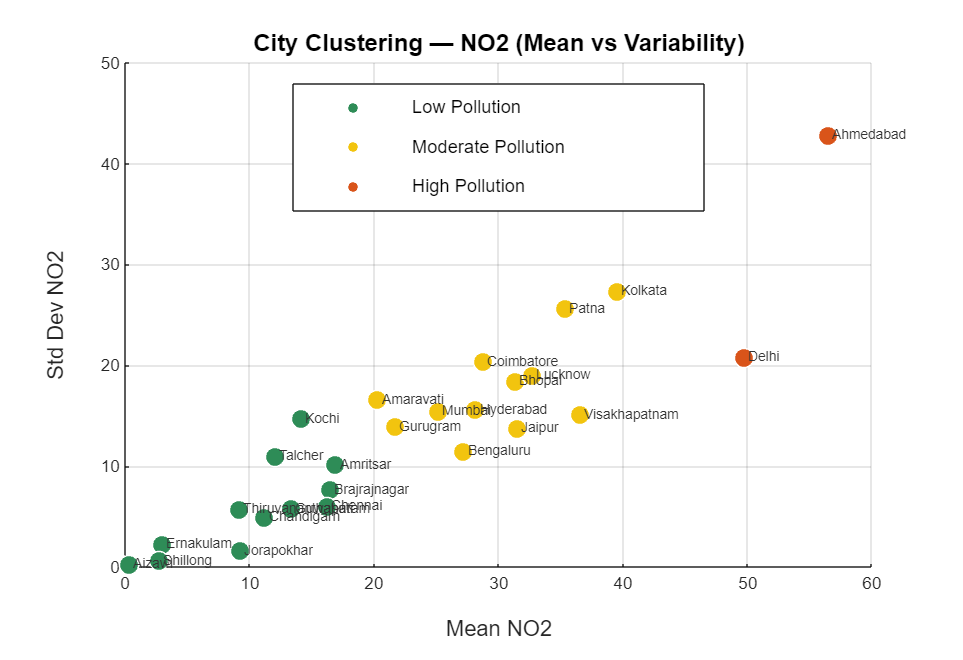

%%  FIGURE 2 — Scatter: Mean vs Std Dev

figure('Name', 'Clustering: Mean vs Std', 'Color', 'w', 'Position', [660 100 700 480]);
hold on;
for c = 1:kOpt
    mask = idx == c;
    scatter(featMean(mask), featStd(mask), 110, colors(c,:), 'filled', ...
            'MarkerEdgeColor', 'w', 'LineWidth', 0.8, 'DisplayName', clusterLabels(c));
end
for i = 1:numel(cities)
    text(featMean(i) + 0.3, featStd(i), cities{i}, 'FontSize', 7.5, 'Color', [0.2 0.2 0.2]);
end
xlabel(['Mean ' mainPollutant],    'FontSize', 12);
ylabel(['Std Dev ' mainPollutant], 'FontSize', 12);
title(['City Clustering — ' mainPollutant ' (Mean vs Variability)'], ...
      'FontSize', 13, 'FontWeight', 'bold');
legend('Location', 'best', 'FontSize', 10);
grid on; box off;

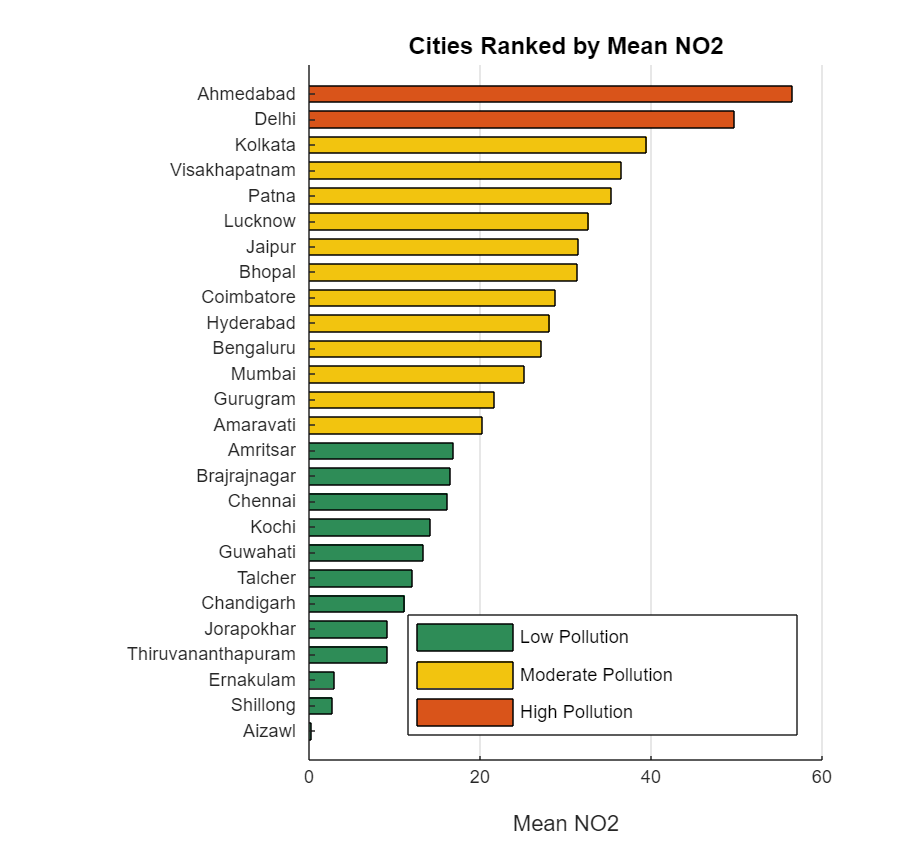

%%  FIGURE 3 — Horizontal Bar: Cities Ranked by Mean Pollutant

figure('Name', 'City Ranking', 'Color', 'w', 'Position', [820 540 660 620]);
[sortedMean, sortOrd] = sort(featMean);
sortedCities = cities(sortOrd);
barColors    = colors(idx(sortOrd), :);
bh = barh(1:numel(cities), sortedMean, 0.65, 'FaceColor', 'flat');
bh.Annotation.LegendInformation.IconDisplayStyle = 'off';
bh.CData = barColors;
yticks(1:numel(cities));
yticklabels(sortedCities);
xlabel(['Mean ' mainPollutant], 'FontSize', 12);
title(['Cities Ranked by Mean ' mainPollutant], 'FontSize', 13, 'FontWeight', 'bold');
hold on;
for c = 1:kOpt
    patch(NaN, NaN, colors(c,:), 'DisplayName', clusterLabels(c));
end
legend('Location', 'southeast', 'FontSize', 10);
grid on; box off;
ax = gca; ax.XGrid = 'on'; ax.YGrid = 'off';

%%   RESULT TABLE

silVals = silhouette(X_norm, idx);

ResultTable = table(cities, round(featMean,2), round(featStd,2), ...
                    round(featMedian,2), round(featP90,2), ...
                    round(featAQI,1), clusterLabels(idx), round(silVals,3), ...
    'VariableNames', {'City','Mean','Std','Median','P90','Mean_AQI','Cluster','Silhouette'});

ResultTable = sortrows(ResultTable, 'Mean', 'descend');

fprintf('\n========== CITY CLUSTERING RESULTS (%s) ==========\n', mainPollutant);


========== CITY CLUSTERING RESULTS (NO2) ==========


disp(ResultTable);

             City             Mean      Std     Median     P90      Mean_AQI          Cluster           Silhouette
    ______________________    _____    _____    ______    ______    ________    ____________________    __________

    {'Ahmedabad'         }    56.49    42.79    45.91     116.59     428.9      "High Pollution"          0.627   
    {'Delhi'             }    49.72     20.8    46.71      78.54     258.2      "High Pollution"          -0.26   
    {'Kolkata'           }    39.51    27.35       32      81.71     139.7      "Moderate Pollution"      0.654   
    {'Visakhapatnam'     }    36.57    15.07    35.23      57.41     111.8      "Moderate Pollution"        0.8   
    {'Patna'             }    35.38  


fprintf('\n--- Cluster Summary ---\n');


--- Cluster Summary ---


for c = 1:kOpt
    mask         = strcmp(ResultTable.Cluster, clusterLabels(c));
    memberCities = strjoin(ResultTable.City(mask), ', ');
    fprintf('%s  (%d cities): %s\n', clusterLabels(c), sum(mask), memberCities);
end

Low Pollution  (12 cities): Amritsar, Brajrajnagar, Chennai, Kochi, Guwahati, Talcher, Chandigarh, Jorapokhar, Thiruvananthapuram, Ernakulam, Shillong, Aizawl
Moderate Pollution  (12 cities): Kolkata, Visakhapatnam, Patna, Lucknow, Jaipur, Bhopal, Coimbatore, Hyderabad, Bengaluru, Mumbai, Gurugram, Amaravati
High Pollution  (2 cities): Ahmedabad, Delhi


fprintf('\nOverall mean silhouette score: %.4f\n', mean(silVals));


Overall mean silhouette score: 0.6583
